## Minidrone State Equations

%Clear the variables from the workspace
clear, clc, close all;
% Set this variable to false if generating figures for evaluation purposes.
% Set as true otherwise.
req_input = true;
% Suppress warnings related to deprecated environment block
warning('off','Simulink:VariantAdvisorChecks:ObsoleteSlEnvironmentControllerBlockCauseWithArg')
%% Create real symbolic variables for states, inputs, MVs and parameters
syms input_1 input_2 input_3 input_4 Ixx Iyy Izz k l m b g real
syms x y z phi theta psi vx vy vz p q r real


where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

$$v_x$
$: x velocity in inertial frame of reference [m/s]

$$v_y$
$: y velocity in inertial frame of refenence [m/s]

$$v_z$$: z velocity in inertial frame of reference [m/s]

$p$: angular velocity around x axis of body coordinate system [rad/s]

$q$: angular velocity around y axis of body coordinate system [rad/s]

$r$: angular velocity around z axis of body coordinate system [rad/s]

**Control Inputs**

$$T_i$$: Thrust produced by rotor $$i$$ along the [0;0;1] axis [N] ($$-$ve$ is upwards).

**Parameters**

$g$: gravitational acceleration [m/s^2]

$b$: rotor drag constant [kg*m^2]

$k$: rotor lift constant [kg*m]

$l$: moment arm between rotor and centre of mass [m]

$I_{ii}$ (Iii): diagonal elements of inertia matrix [kg*m^2]

For the Parrot drone, the parameters are:

load UAV_NominalParameters % Make sure this is in your path
%IxxVal  %Units kg * m^2
%IyyVal  %Units kg * m^2
%IzzVal  %Units kg * m^2
%kVal  %Units N * s^2 = kg * m
%lVal  %Units m
%mVal  %Units kg
%bVal  %Units N * m * s^2= kg * m^2
gVal = 9.81; %Units kg * m / s^2

paramValues = [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal]

paramValues =     0.0001    0.0001    0.0001    0.0000    0.0441    0.0630    0.0000    9.8100


During the flight, the quadcopter's coordinate system will be rotating. Therefore, we need to relate it to the global coordinates using a rotational matrix

%R-ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1]

$$Rz = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx

$$R\_Euler = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

The thrust generated by the rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Recall that our input for motor $i$ is simply the thrust $$$T_i$$$ which it generates. Therefore, the total thrust generated is 

% Thrust force
Fz = (input_1 + input_2 + input_3 + input_4);

The produced thrust also generates moments around the x and y-axis:


$$$$L_i=\pm l \cdot T_i$$$$



$$$$M_i=\pm l \cdot T_i$$$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axes.

The thrust generated by a single rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i = \pm \frac{b}{k} \cdot T_i $$$


where $c_D$ is the drag coefficient related to the blade geometry. Where all of the constant variables except for $$F_{z_i}}$$  and $k$ are substituted by a single parameter $b$. Therefore, the total moments acting on the vehicle are:

% Moments
L = l * (- input_1 + input_2 + input_3 - input_4);
M = l * (- input_1 - input_2 + input_3 + input_4);
N = (b ./ k) * (input_1 - input_2 + input_3 - input_4);

Note the positive moments are defined by the right-hand rule. 

Having defined the forces and moments acting on the system and the rotation matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [vx; vy; vz];

The Euler angles rates are

% Euler angles rates
f(4) = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
f(5) = q * cos(phi) - r * sin(phi);
f(6) = (q * sin(phi) + r * cos(phi)) / cos(theta);

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
f(7:9) = R_Euler*[0;0;Fz]/m + [0;0;g];

Using the vector transport theorem, the angular acceleration of the system can be defined as

% Rotational Acceleration
f(10) = (L + (Iyy - Izz) * q * r) / Ixx;
f(11) = (M + (Izz - Ixx) * p * r) / Iyy;
f(12) = (N + (Ixx - Iyy) * p * q) / Izz;

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameter variables with their respective values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
f = subs(f, [Ixx Iyy Izz k l m b g], paramValues);      
f = simplify(f);      

Let us now group the states and normalised control inputs:

% Group symbolic variables
state = [x y z phi theta psi vx vy vz p q r];
control = [input_1, input_2, input_3, input_4];

Having now defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate linearization
A = jacobian(f,state)

B = jacobian(f,control)

$$B = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3}\\ -\frac{2033753534126478065664}{2688151780141324375} & \frac{2033753534126478065664}{2688151780141324375} & \frac{2033753534126478065664}{2688151780141324375} & -\frac{2033753534126478065664}{2688151780141324375}\\ -\frac{2033753534126478065664}{3306117706610594375} & -\frac{2033753534126478065664}{3306117706610594375} & \frac{2033753534126478065664}{3306117706610594375} & \frac{2033753534126478065664}{3306117706610594375}\\ \frac{2326529382815569375}{114122597371620992} & -\frac{2326529382815569375}{114122597371620992} & \frac{2326529382815569375}{114122597371620992} & -\frac{2326529382815569375}{114122597371620992} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1000\,\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{63}-\frac{1000\,\cos\left(\psi \right)\,\sin\left(\varphi \right)}{63}\\ \sigma_{2}=\frac{1000\,\sin\left(\varphi \right)\,\sin\left(\psi \right)}{63}+\frac{1000\,\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{63}\\ \sigma_{3}=\frac{1000\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{63} \end{array}$$

f_StatesZero = subs(f, state, zeros(1,12));                       
[input_Eq1, input_Eq2, input_Eq3, input_Eq4] = solve(f_StatesZero == 0, control);     
input_Eq = double([input_Eq1 input_Eq2 input_Eq3 input_Eq4])               

input_Eq =    -0.1545   -0.1545   -0.1545   -0.1545


%Save the result in a mat file
save('Equilibrium inputs', 'input_Eq')

## Ensure that the Dependencies for the Parrot Model are Installed Properly

ver_info = struct2array(ver);
simulink_installed = contains(ver_info, 'Simulink')
aero_installed = contains(ver_info, 'Aerospace Toolbox')
aero_block_installed = contains(ver_info, 'Aerospace Blockset')
cv_installed = contains(ver_info, 'Computer Vision Toolbox')
signal_installed = contains(ver_info, 'Signal Processing Toolbox')
threeD_installed = contains(ver_info, 'Simulink 3D Animation')
parrot_support_installed = isParrotSupportPkgInstalled
if simulink_installed && aero_installed && aero_block_installed && cv_installed && signal_installed && threeD_installed && parrot_support_installed
    disp('All dependencies are met.')
else
    error('Missing model dependencies. Ensure that all of the requirements are properly installed before proceeding.')
end

## LAB LQR position controller design

Ts = 0.005; % sampling time
A1 = eval(subs(A,[state control],[zeros(1,12) input_Eq]));
B1 = eval(subs(B,[state control],[zeros(1,12) input_Eq]));
C1 = [1 zeros(1,11); 0 1 zeros(1,10); 0 0 1 zeros(1,9); 0 0 0 0 0 1 zeros(1,6)]

C1 =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0



Ctsys = ss(A1,B1,C1,[]); %ct system
Dtsys = c2d(Ctsys,Ts);

Q1 = diag([20,20,20,1,1,20,1,1,1,1,1,1])  % higher = harder feedback on state error 20

Q1 =     20     0     0     0     0     0     0     0     0     0     0     0
     0    20     0     0     0     0     0     0     0     0     0     0
     0     0    20     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0    20     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0


R1 = 0.01*eye(4) ; % higher = lower input/ less responsive 0.01

[K,~,E] = lqrd(A1,B1,Q1,R1,Ts)

K =     0.4521   -0.3677   11.6780   -0.6233   -0.7665   10.1456    0.2844   -0.2313    2.6808   -0.0847   -0.1041    2.3228
    0.4521    0.3677   11.6780    0.6233   -0.7665  -10.1456    0.2844    0.2313    2.6808    0.0847   -0.1041   -2.3228
   -0.4521    0.3677   11.6780    0.6233    0.7665   10.1456   -0.2844    0.2313    2.6808    0.0847    0.1041    2.3228
   -0.4521   -0.3677   11.6780   -0.6233    0.7665  -10.1456   -0.2844   -0.2313    2.6808   -0.0847    0.1041   -2.3228


E =    0.9892 + 0.0150i
   0.9892 - 0.0150i
   0.9892 + 0.0150i
   0.9892 - 0.0150i
   0.9842 + 0.0000i
   0.9842 + 0.0000i
   0.9779 + 0.0000i
   0.9779 + 0.0000i
  -0.2675 + 0.0000i
  -0.2672 + 0.0000i


E = abs(E)

E =     0.9893
    0.9893
    0.9893
    0.9893
    0.9842
    0.9842
    0.9779
    0.9779
    0.2675
    0.2672



%lqrd 
% convert A and B to DT

if req_input
open_system('LQR/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR/HoverWithLQR.prj');

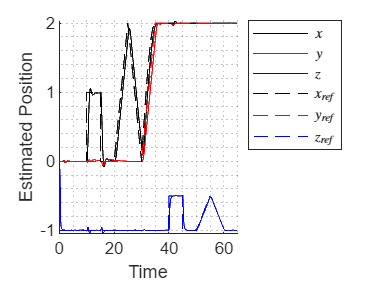

simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");

% Plot Position
figure(3)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
grid minor

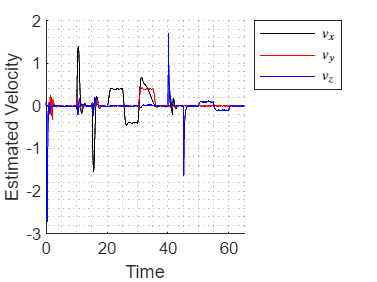


% Plot Velocity
figure(4)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
grid minor

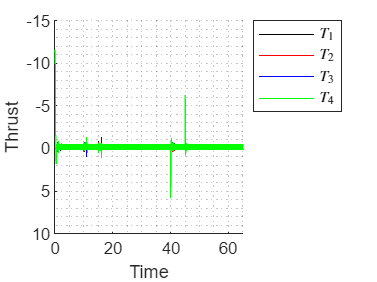


% Plot Thrust
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
grid minor
hold off


if req_input
input('Press "Enter" key to continue...')
end

close(lqrProj)

## Data-Driven Approach Indexing

% State estimations obtained following simulation run
% simInfo.estimatedStates.signals.values

% Specific state data can be extracted using matrix indexing
% sim1to3 = simInfo.estimatedStates.signals.values(:,1:3);
% sim6 = simInfo.estimatedStates.signals.values(:,6);

% sim data for states 1,2,3 and 6 
% Xdata = [sim1to3 sim6] ;
Xdata = simInfo.estimatedStates.signals.values;
% XDataPosDD1 = double(Xdata');
% Xdata = double(Xdata');
% XExptcorrected = double(Xdata');


% Break into X0,T and X1,T
Xdata0 = Xdata(:,1:end-1);
Xdata1 = Xdata(:,2:end);

## Convex Optimiser (*not LQR)

% convex optimiser to find a Q that satisfies the following constraint
cvx_begin sdp
    variable Q(13000,12)
    %main constraint
    [Xdata0*Q Xdata1*Q;Q'*Xdata1' Xdata0*Q] > 10^(-9)*eye(2*12)
cvx_end

## Convex Optimiser for LQR Controller

% W is the controllability grammian --> use 'gram' to compute --> n x n
% size
% Xdum here is R^(0.5)*K*W*K'*R^(0.5) --> R is specified

% Check with rank function
% Initialise inputs --> different inputs at different time steps --> to
% meet rank condition --> add a tiny amount of noise --> 0.01 * rand
U = zeros(4,13000);
% U(1,:) = input_Eq(1);
% U(2,:) = input_Eq(2);
% U(3,:) = input_Eq(3);
% U(4,:) = input_Eq(4);

for i=1:13000
    U(1,i) = rand(1);
    U(2,i) = rand(1);
    U(3,i) = rand(1);
    U(4,i) = rand(1);
end

Rroot = R1^0.5;

cvx_begin sdp
    variables Q2(13000,12) Xdum(4,4)  
    minimize( trace(Q1*Xdata0*Q2) + trace(Xdum) ) 
    subject to
        [Xdum Rroot*U*Q2;Q2'*U'*Rroot Xdata0*Q2] >= 0
        [Xdata0*Q2-eye(12) Xdata1*Q2;Q2'*Xdata1' Xdata0*Q2] >= 0
cvx_end

## Solve for Data-Driven Gain K

% Solve for K
Kdata = U*Q2*inv(Xdata0*Q2); % only 1 of the stabilising K (can have multiple)
% Kdatacorrected = zeroes(4,12);

## CODE TESTER (Plot trajectories)

% reference trajectories
figure(3)
clf
hold on
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k-')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r-')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b-')
legend('$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time (s)','Interpreter','Latex')
ylabel('Estimated Position','Interpreter','Latex')
grid minor
hold off
print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\ReferencePos','-dpng','-r300')

%% 3D Plot
plot3(simInfo.estimatedStates.signals.values(:,1), simInfo.estimatedStates.signals.values(:,2),simInfo.estimatedStates.signals.values(:,3))
grid on

## Plot Position Separately

%% Plot Position Separately
clf
figure
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
hold on
plot(simInfo.estimatedStates.time,XDataPosmodel(:,1),'Color',[0.9290, 0.6940, 0.1250])
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
legend('$x_{data}$','$x_{model}$','$x_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time(s)')
ylabel('Estimated Position')
grid minor
hold off
print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\XPosData1','-dpng','-r300')

figure
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
hold on
plot(simInfo.estimatedStates.time,XDataPosmodel(:,2),'Color',[0.9290, 0.6940, 0.1250])
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
legend('$y_{data}$','$y_{model}$','$y_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time(s)')
ylabel('Estimated Position')
grid minor
hold off
print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\YPosData1','-dpng','-r300')

figure
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
hold on
plot(simInfo.estimatedStates.time,XDataPosmodel(:,3),'Color',[0.9290, 0.6940, 0.1250])
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$z_{data}$','$z_{model}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time(s)')
ylabel('Estimated Position')
grid minor
hold off
print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\ZPosData2','-dpng','-r300')

## Subplot version of ^

figure
subplot(3, 1, 1);
plot(simInfo.estimatedStates.time(1:11000),Xsmooth(1:11000),'k','LineWidth',1.0);
hold on
plot(simInfo.estimatedStates.time(1:11000),simInfo.estimatedStates.signals.values(1:11000,1),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k','LineWidth',1.0)
% [0, 0.4470, 0.7410]
% plot(simInfo.estimatedStates.time,XDataPosmodel(:,1),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
legend('$x_{model}$','$x_{data}$','$x_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
ylabel('x','Interpreter','Latex','FontSize',12)
grid minor
hold off

subplot(3, 1, 2);
plot(simInfo.estimatedStates.time(1:11000),Ysmooth(1:11000),'Color',[1, 0, 0],'LineWidth',1.0);
hold on
plot(simInfo.estimatedStates.time(1:11000),Ydatasmooth(1:11000),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time(1:11000),simInfo.estimatedStates.signals.values(1:11000,2),'Color',[0, 0.4470, 0.7410],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'Color',[1, 0, 0],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time,XDataPosmodel(:,2),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
legend('$y_{model}$','$y_{data}$','$y_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
ylabel('y','Interpreter','Latex','FontSize',12)
grid minor
hold off

subplot(3, 1, 3);
plot(simInfo.estimatedStates.time(1:11000),Zsmooth(1:11000),'Color',[0, 0, 1],'LineWidth',1.0);
hold on
 plot(simInfo.estimatedStates.time(1:11000),simInfo.estimatedStates.signals.values(1:11000,3),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'Color',[0, 0, 1],'LineWidth',1.0)
% plot(simInfo.estimatedStates.time,XDataPosmodel(:,3),'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1.0)
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$z_{model}$','$z_{data}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time(s)','Interpreter','Latex')
ylabel('z','Interpreter','Latex','FontSize',12)
grid minor
hold off

print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\SubplotXYZSmoothData3','-dpng','-r300')

## Error calculations 

Err1rms = rmse(simInfo.estimatedStates.signals.values(1:11000,1),cmds.ans.Data(1:11000,1))

Err1rms = single
0.1796

Err1 = (simInfo.estimatedStates.signals.values(1:11000,1) - cmds.ans.Data(1:11000,1))/max(simInfo.estimatedStates.signals.values(1:11000,1))*100

Err1 = 11000×1 single column vector
         0
         0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


% plot(cmds.ans.Time(1:11000),Err1,'-','Color',[0,0,0])
% ylabel("$x_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor

Err2rms= rmse(simInfo.estimatedStates.signals.values(1:11000,2),cmds.ans.Data(1:11000,2))

Err2rms = single
0.0734

Err2 = (simInfo.estimatedStates.signals.values(1:11000,2) - cmds.ans.Data(1:11000,2))/max(simInfo.estimatedStates.signals.values(1:11000,2))*100

Err2 = 11000×1 single column vector
         0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


% plot(cmds.ans.Time(1:11000),Err2,'-','Color',[1,0,0])
% ylabel("$y_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor
 
Err3rms = rmse(simInfo.estimatedStates.signals.values(1:11000,3),cmds.ans.Data(1:11000,3))

Err3rms = single
0.0825

Err3 = (simInfo.estimatedStates.signals.values(1:11000,3) - cmds.ans.Data(1:11000,3))/max(simInfo.estimatedStates.signals.values(1:11000,3))

Err3 = 11000×1 single column vector
  -21.6747
  -21.6747
  -21.6801
  -21.6900
  -21.7019
  -21.7122
  -21.7184
  -21.7198
  -21.7162
  -21.7075


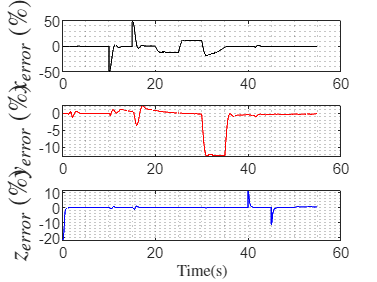

% plot(cmds.ans.Time(1:11000),Err3,'-','Color',[0,0,1])
% ylabel("$z_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor

% Create figure
figure;

% First subplot
subplot(3, 1, 1);
% Example plot for the first subplot
plot(cmds.ans.Time(1:11000),Err1,'-','Color',[0,0,0])
ylabel("$x_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor


% Second subplot
subplot(3, 1, 2);
% Example plot for the second subplot
plot(cmds.ans.Time(1:11000),Err2,'-','Color',[1,0,0])
ylabel("$y_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor


% Third subplot
subplot(3, 1, 3);
% Example plot for the third subplot
plot(cmds.ans.Time(1:11000),Err3,'-','Color',[0,0,1])
ylabel("$z_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor
xlabel("Time(s)",'Interpreter','Latex')


% print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\xyzErrorsDD2','-dpng','-r300')

## Smoothing

Xsmooth = XExptUncorrected(:,1);
Ysmooth = XExptUncorrected(:,2);
Zsmooth = XExptUncorrected(:,3);

% Xsmooth = wdenoise(Xsmooth, 'DenoisingMethod', 'Bayes');
% Ysmooth = wdenoise(Ysmooth, 'DenoisingMethod', 'Bayes');
% Zsmooth = wdenoise(Zsmooth, 'DenoisingMethod', 'Bayes');

windowsizeY = 400;
windowsizeZ = 150;
% Xsmooth = movmean(Xsmooth, windowsize);
Ysmooth = movmean(Ysmooth, windowsizeY);
Zsmooth = movmean(Zsmooth, windowsizeZ);

windowsizeY2 = 400; % 15 150 200 400
% windowsizeZ2 = 400:
Ydatasmooth = movmean(Xdata(:,2), windowsizeY2);
% Zdatasmooth = movmean(Xdata(:,3), windowsizeZ2);

## Error calculations Expt 

Err1rms = rmse(simInfo.estimatedStates.signals.values(1:11000,1),cmds.ans.Data(1:11000,1))
Err1 = (Xsmooth(1:11000)-simInfo.estimatedStates.signals.values(1:11000,1))/max(Xsmooth(1:11000))*100
% plot(cmds.ans.Time(1:11000),Err1,'-','Color',[0,0,0])
% ylabel("$x_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor

Err2rms= rmse(simInfo.estimatedStates.signals.values(1:11000,2),cmds.ans.Data(1:11000,2))
Err2 = (Ysmooth(1:11000) - Ydatasmooth(1:11000))/max(Ysmooth(1:11000))*100
% plot(cmds.ans.Time(1:11000),Err2,'-','Color',[1,0,0])
% ylabel("$y_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor
 
Err3rms = rmse(simInfo.estimatedStates.signals.values(1:11000,3),cmds.ans.Data(1:11000,3))
Err3 = (Zsmooth(1:11000) - simInfo.estimatedStates.signals.values(1:11000,3))/max(Zsmooth(1:11000))*100
% plot(cmds.ans.Time(1:11000),Err3,'-','Color',[0,0,1])
% ylabel("$z_{error}$ ($\%$)",'Interpreter','Latex')
% grid minor

% Create figure
figure;

% First subplot
subplot(3, 1, 1);
% Example plot for the first subplot
plot(cmds.ans.Time(1:11000),Err1,'-','Color',[0,0,0])
ylabel("$x_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor


% Second subplot
subplot(3, 1, 2);
% Example plot for the second subplot
plot(cmds.ans.Time(1:11000),Err2,'-','Color',[1,0,0])
ylabel("$y_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor


% Third subplot
subplot(3, 1, 3);
% Example plot for the third subplot
plot(cmds.ans.Time(1:11000),Err3,'-','Color',[0,0,1])
ylabel("$z_{error}$ ($\%$)",'Interpreter','Latex','FontSize',14)
grid minor
xlabel("Time(s)",'Interpreter','Latex')

print('C:\Users\vikas\OneDrive\Desktop\FYP Diagrams\xyzErrorsExpt2','-dpng','-r300')